prbs = ltePRBS(7, 100, "signed")

prbs =      1
    -1
     1
     1
     1
     1
    -1
     1
    -1
     1


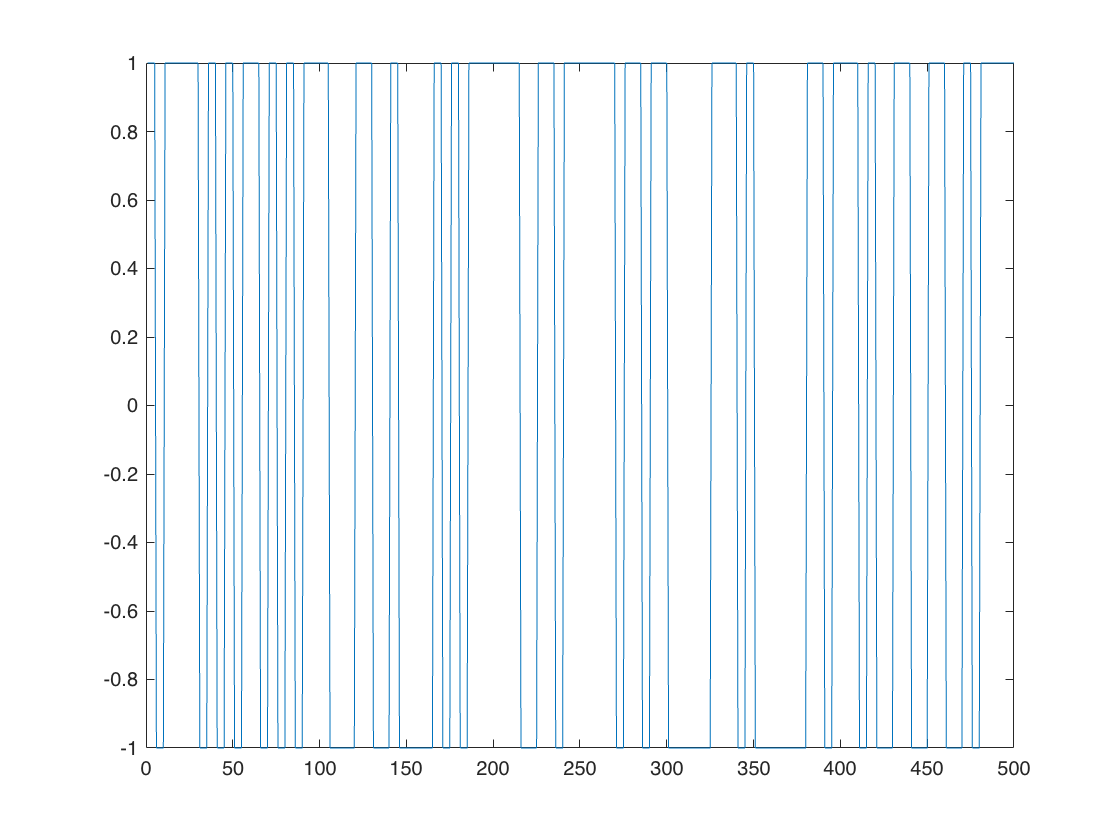

sig = [];
for m = 1:100
    sig = [sig prbs(m) * ones(1, 5)];
end
plot(sig);

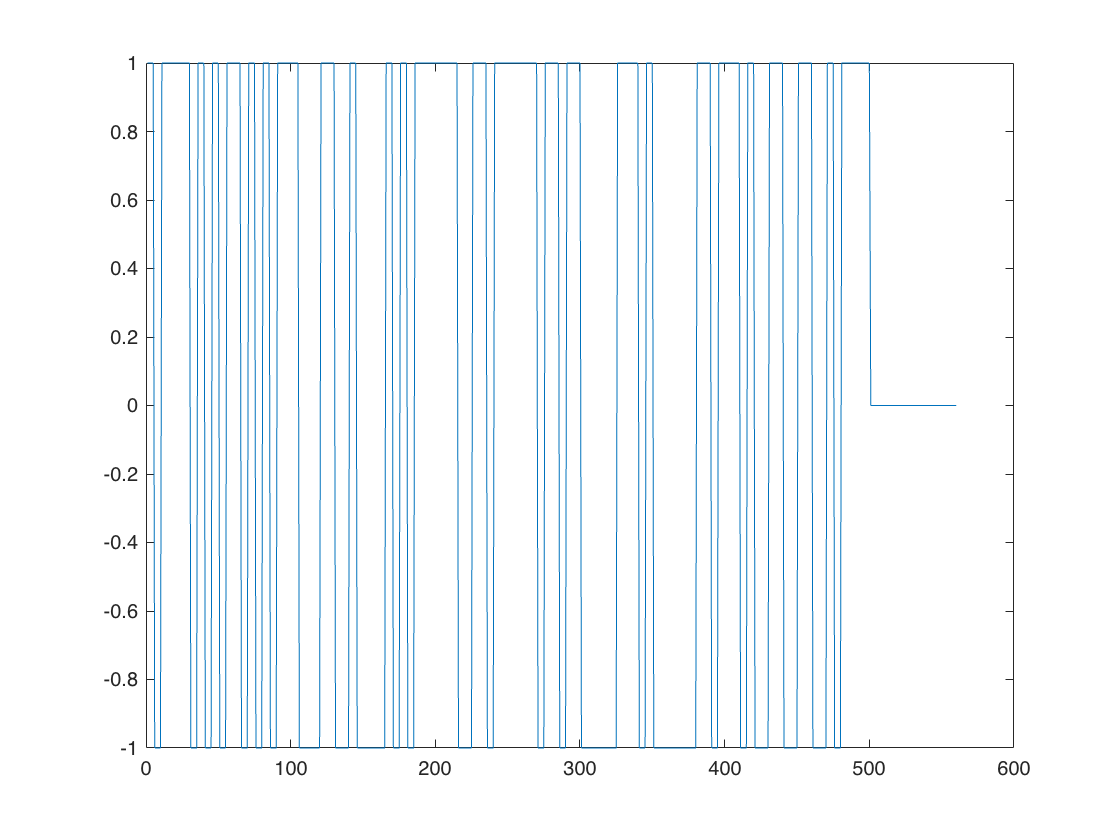


c = rcosdesign(1, 20, 6);

delay = floor(length(c) / 2);
sig = [sig zeros(1,delay)];
plot(sig)

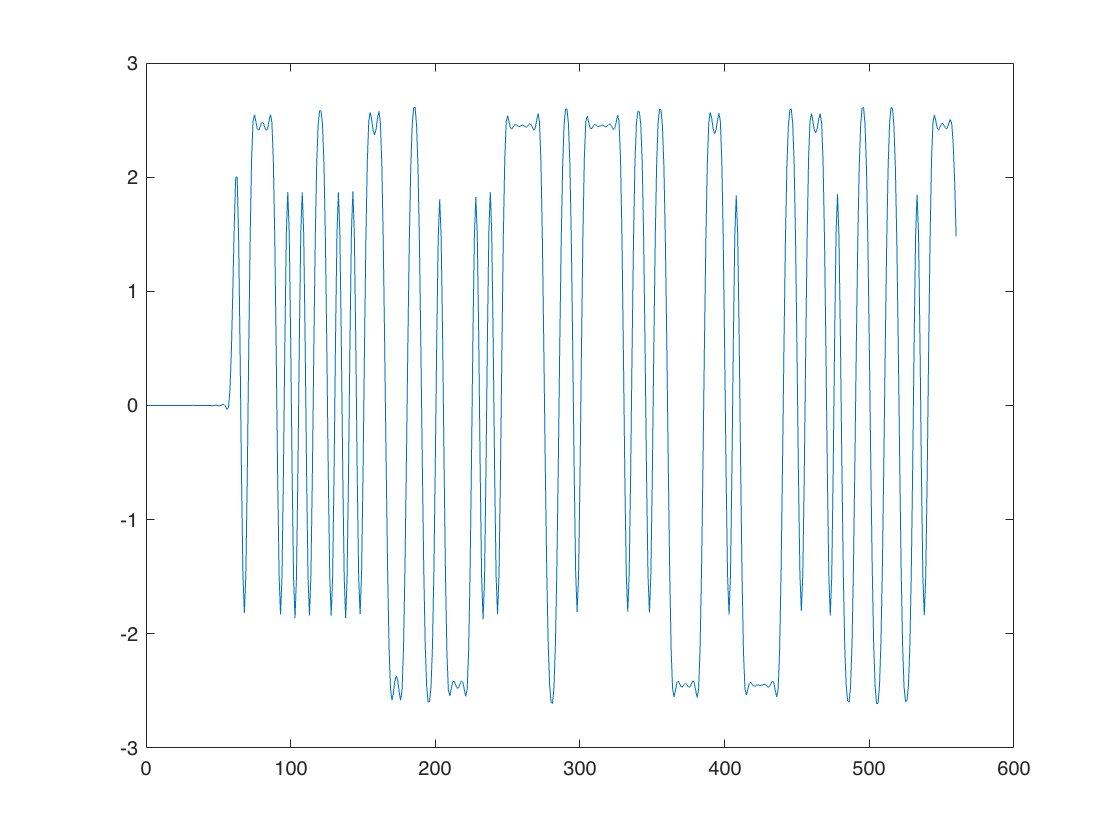

sig = filter(c, 1, sig);
plot(sig)

sig = sig(delay + 1:end)

sig =     1.5818    1.9955    2.0018    1.4802    0.5163   -0.5995   -1.4823   -1.8149   -1.4848   -0.6227    0.4713    1.4724    2.1625    2.4909    2.5476    2.4827    2.4194    2.4113    2.4450    2.4773    2.4747    2.4402    2.4091    2.4223    2.4875    2.5494    2.4867    2.1564    1.4718    0.4789   -0.6141   -1.4863   -1.8301   -1.4969   -0.5882    0.5601    1.5036    1.8705    1.5154    0.5771   -0.5797   -1.5111   -1.8640   -1.5071   -0.5766    0.5761    1.5113    1.8688    1.5075    0.5664


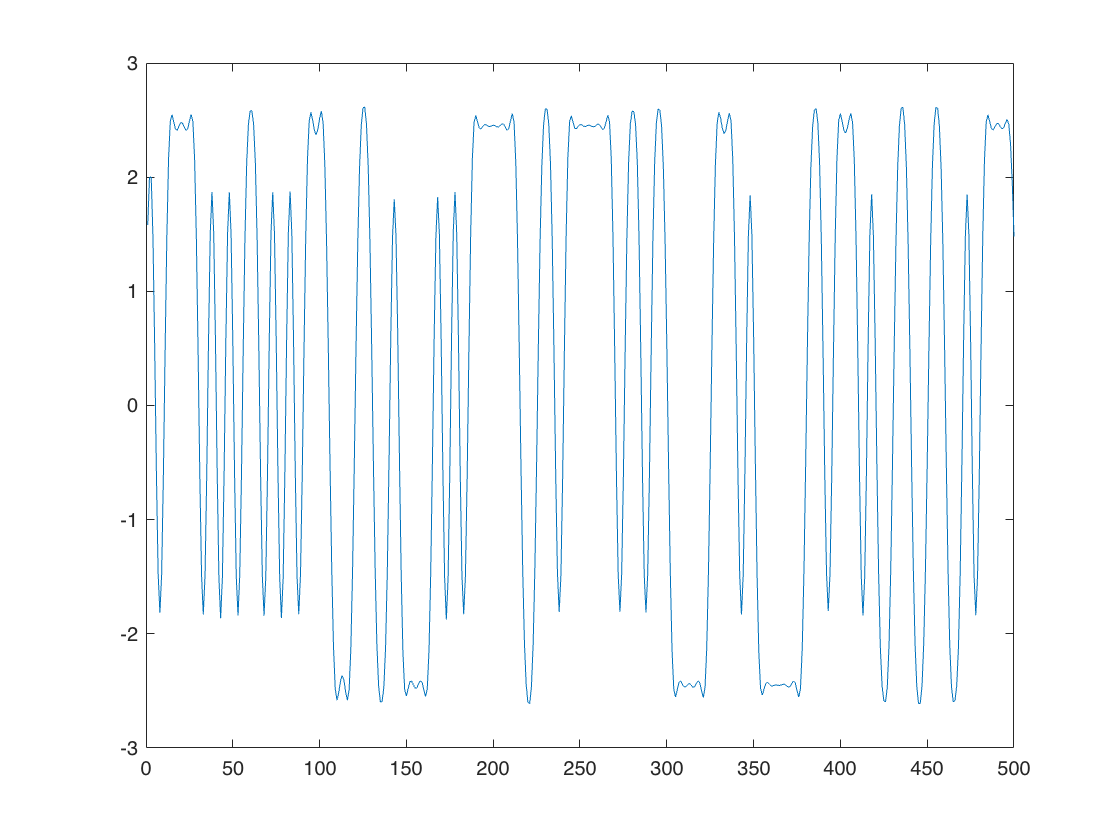

plot(sig)